## Results

Figure 2 below is a contour plot of every possible shot within our ranges of 9.5-11.5 m/s launch speed and 30-60 degrees launch angle, with green representing a made shot and red representing a miss. As such, the height of the green band at any angle represents the margin of error for that angle - the difference between the fastest and slowest possible speeds that results in a made shot. Within this graph, it can be seen that the range starts small at a lower angle and gets continuously larger as the angle increases.

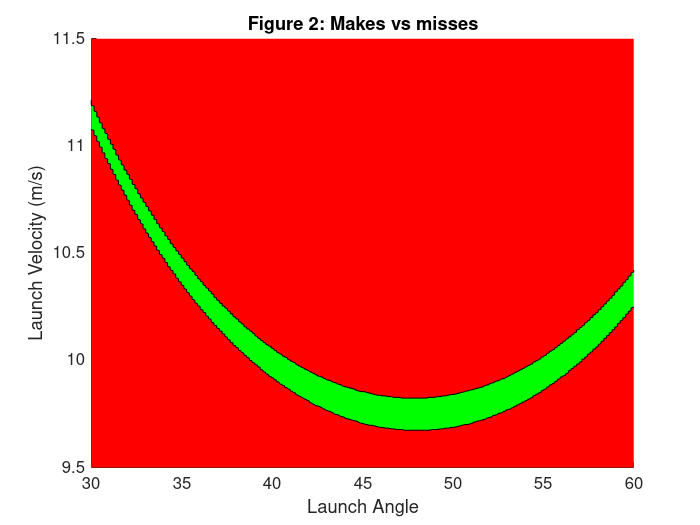

gen_contour_plot()

Author's note: because of the resolution of our data, the graph appears jittery and it seems as though the margin of error shrinks as the angle goes past 50 degrees or so, however this is not the case. If the staggered areas were smoothed out, then it would be more clear that the margin of error actually continues to increase, however due to time and computational constraints, we were unable to increase the resolution in our data. We have also included Figure 3 below to help make this trend clearer.

Figure 3 below graphs the size of the margin of error itself for each angle, where it is very clear that the margin of error continues to grow as the angle increases. 

One effect of increasing launch angle is that the speed required to make the shot increases as well. Because it is less tiring and easier to be consistent with a slower speed, the optimal angle to release the ball and the answer to our initial modeling question would be the smallest angle that still provides the greatest margin of error which is denotated with the red dot at 58.99 degrees.

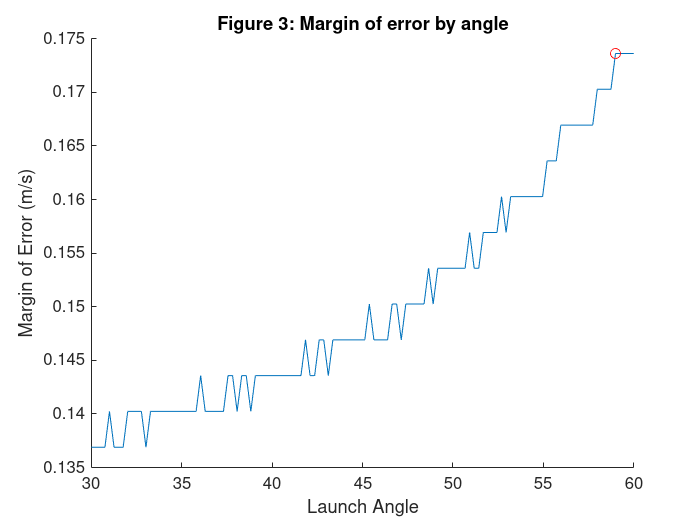

[angles, moes] = sweep_angle_moe();
figure; clf; hold on;
plot(angles, moes)
title('Figure 3: Margin of error by angle')
xlabel('Launch Angle')
ylabel('Margin of Error (m/s)')
plot(58.9916, .1736, 'ro')

Note: Once again, the small jitters in this graph are caused by not having high enough resolution in our shot speed parameter sweep. We have attempted to mitigate this by increasing the number of steps taken and reducing the range in which we sweep to squeeze in some extra density, but time and computation constraints have prevented us from attempting any further optimization.

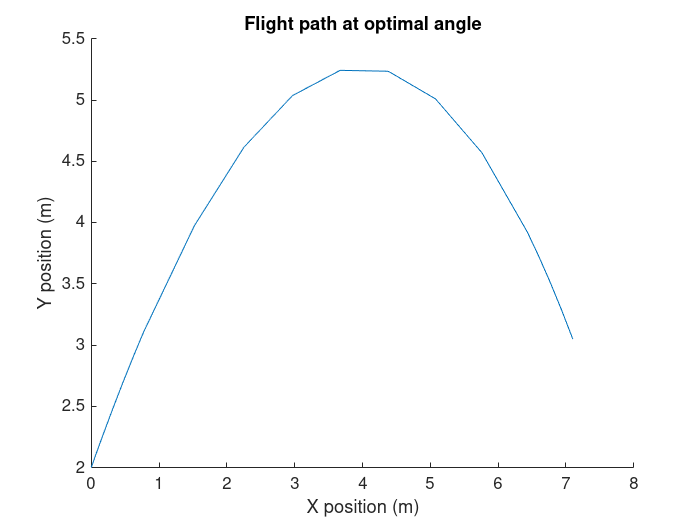

 [T, U] = bball_trajectory(10, 57.45);
 figure; clf; hold on;
 plot(U(:, 1), U(:, 2))
 title('Flight path at optimal angle')
 xlabel('X position (m)')
 ylabel('Y position (m)')